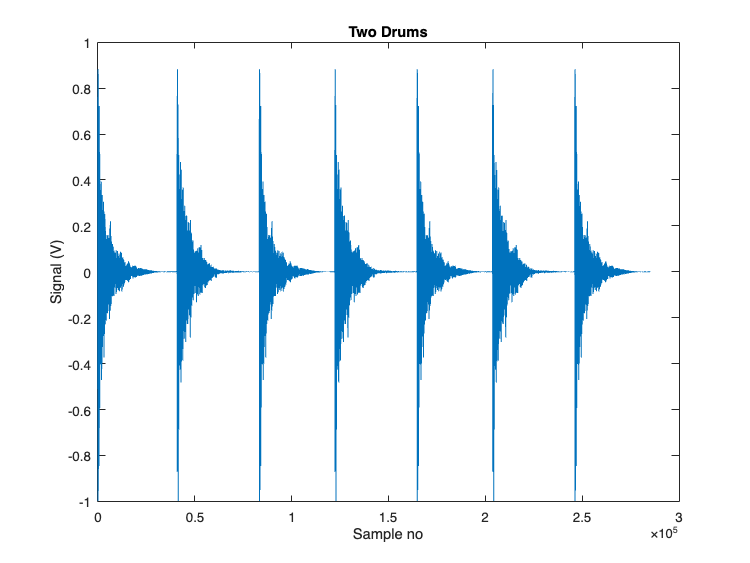

clear all
[sig fs] = audioread('two_drums.wav');
sound(sig, fs)

figure(1);
clf;
plot(sig);
xlabel('Sample no');
ylabel('Signal (V)');
title('Two Drums');

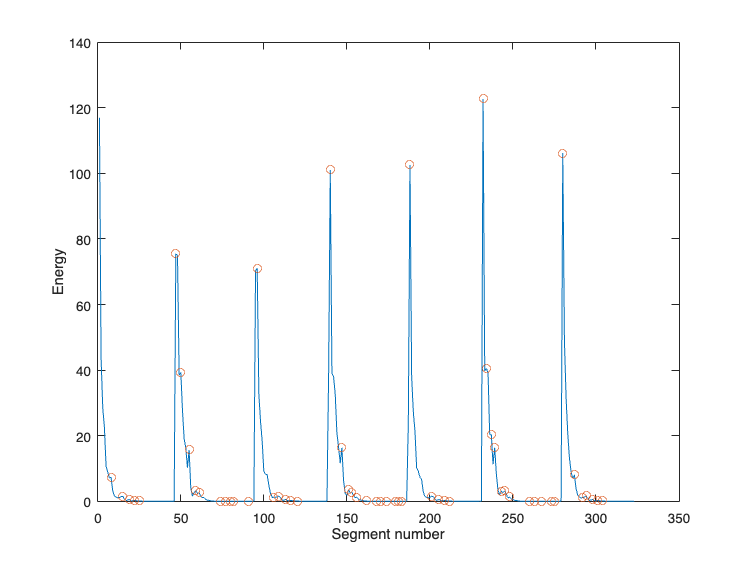


% Divide signal into segments and find its energy
T = 0.02;                  % Duration of each segment (20ms)
N = fs * T;                % Number of samples per segment
E = [];                    % Initialize an empty array to store energy values

for i = 1:N:length(sig)-N+1
    seg = sig(i:i+N-1);    % Extract segment from signal
    E = [E seg' * seg];    % Calculate and store energy of the segment
end

% Plot the energy graph and the peak values
figure(2);
clf;
x = 1:length(E);           % Segment indices
plot(x, E);                % Plot energy of each segment
xlabel('Segment number');  % Label for x-axis
ylabel('Energy');          % Label for y-axis
hold on;

% Find local maxima
[pks, locs] = findpeaks(E); % Find peaks and their locations
plot(locs, pks, 'o');       % Highlight peaks on the energy graph
hold off;

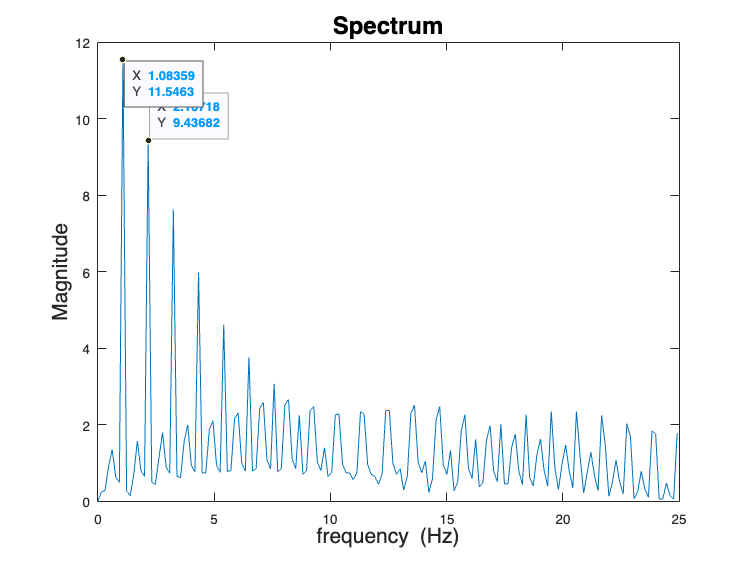


% Plot spectrum of energy
figure(3);
plot_spec(E - mean(E), 1/T); % Plot the energy spectrum (frequency domain)